# **Units in Physics Calculations**

This example shows how to work with units in physics calculations. Calculate the terminal velocity of a falling paratrooper in both SI and imperial units. Solve the motion of the paratrooper, taking into account the gravitational force and the drag force.

## **Introduction**

Imagine a paratrooper jumping out of an airplane. Assume there are only two forces acting on the paratrooper: the gravitational force and an opposing drag force from the parachute. The drag force is proportional to the velocity squared of the paratrooper.

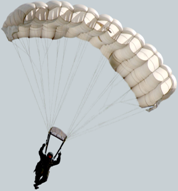

The net force acting on the paratrooper can be expressed as

$\textrm{mass}\cdot \textrm{acceleration}=\textrm{drag}\;\textrm{force}-\textrm{gravitational}\;\textrm{force}$,

$m\frac{\partial }{\partial t}v\left(t\right)=c_d {v\left(t\right)}^2 -m\;g$,

where

- $m$ is the mass of the paratrooper

- *g *is the gravitational acceleration

- $v(t) $is the velocity of the paratrooper

- $c_d$ is the drag constant

## **Define and Solve Equation of Motion**

Define the differential equation describing the equation of motion.

syms g m c_d
syms v(t)
eq = m*diff(v(t),t) + m*g == c_d*v(t)^2

$$eq = m\,\frac{\partial }{\partial t}v\left(t\right)+g\,m=c_{d}\,{v\left(t\right)}^{2}$$

Assume that the parachute opens immediately at $t=0$ so that the equation `eq` is valid for all values of $t\ge 0$.  Solve the differential equation analytically using `dsolve` with the initial condition $v\left(0\right)=0$. The solution represents the velocity of the paratrooper as a function of time.

velocity = simplify(dsolve(eq, v(0) == 0))

$$velocity = -\frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{c_{d}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{c_{d}}}$$

## Find Unit of Drag Constant

Find the SI unit of the drag constant $c_d$.

The SI unit of force is the Newton $\left(N\right)$. In terms of the base units, the Newton is $\left(\frac{\textrm{kg}\cdot m}{s^2 }\right)$. Since these are equivalent, they have a unit conversion factor of 1.

u = symunit;
unitConversionFactor(u.N, u.kg*u.m/u.s^2)

$$ans = 1$$

The drag force $c_d {v\left(t\right)}^2$ must have the same unit in Newton $\left(N\right)$ as the gravitational force $m\, g $. Using dimensional analysis, solve for the unit of $c_d$.

syms drag_units_SI
drag_units_SI = simplify(solve(drag_units_SI * (u.m / u.s)^2 == u.N))

$$drag\_units\_SI = \frac{\mathrm{kg}}{m}$$

## Estimate Terminal Velocity

Describe the motion of the paratrooper by defining the following values.

- Mass of the paratrooper $m\;=\;70\;\textrm{kg}$  

- Gravitational acceleration $g\;=\;9\ldotp 81\;m/s^2$ 

- Drag coefficient $c_d \;=\;40\;\textrm{kg}/m$

Substitute these values into the velocity equation and simplify the result.

vel_SI = subs(velocity,[g,m,c_d],[9.81*u.m/u.s^2, 70*u.kg, 40*drag_units_SI])

$$vel\_SI = -\frac{\tanh\left(\frac{t\,\sqrt{40\,\frac{\mathrm{kg}}{m}}\,\sqrt{\frac{981}{100}\,\frac{m}{s^{2}}}}{\sqrt{70\,\mathrm{kg}}}\right)\,\sqrt{70\,\mathrm{kg}}\,\sqrt{\frac{981}{100}\,\frac{m}{s^{2}}}}{\sqrt{40\,\frac{\mathrm{kg}}{m}}}$$

vel_SI = simplify(vel_SI)

$$vel\_SI = -\frac{3\,\sqrt{763}\,\tanh\left(\frac{3\,\sqrt{763}\,t}{35}\,\frac{1}{s}\right)}{20}\,\frac{m}{s}$$

Compute a numerical approximation of the velocity to 3 significant digits.

digits(3)
vel_SI = vpa(vel_SI)

$$vel\_SI = -4.14\,\tanh\left(2.37\,t\,\frac{1}{s}\right)\,\frac{m}{s}$$

The paratrooper approaches a constant velocity when the gravitational force is balanced by the drag force. This is called the terminal velocity and it occurs when the drag force from the parachute cancels out the gravitational force (there is no further acceleration). Find the terminal velocity by taking the limit of $t\longrightarrow \infty$.

vel_term_SI = limit(vel_SI, t, Inf)

$$vel\_term\_SI = -4.14\,\frac{m}{s}$$

## **Convert Velocity to Imperial Units**

Finally, convert the velocity function from SI units to imperial units.

vel_Imperial = rewrite(vel_SI,u.ft)

$$vel\_Imperial = -13.6\,\tanh\left(2.37\,t\,\frac{1}{s}\right)\,\frac{\mathrm{ft}}{s}$$

Convert the terminal velocity.

vel_term_Imperial = rewrite(vel_term_SI,u.ft)

$$vel\_term\_Imperial = -13.6\,\frac{\mathrm{ft}}{s}$$

## Plot Velocity over Time

To plot the velocity as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T
vel_SI = subs(vel_SI, t, T*u.s)

$$vel\_SI = -4.14\,\tanh\left(2.37\,T\right)\,\frac{m}{s}$$

vel_Imperial = rewrite(vel_SI, u.ft)

$$vel\_Imperial = -13.6\,\tanh\left(2.37\,T\right)\,\frac{\mathrm{ft}}{s}$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[data_SI, units_SI] = separateUnits(vel_SI);
[data_Imperial, units_Imperial] = separateUnits(vel_Imperial);

The velocity of the paratrooper approaches steady state when $t>1$. Show how the velocity approaches terminal velocity by plotting the velocity over the range $0\;\le T\;\le 2$.

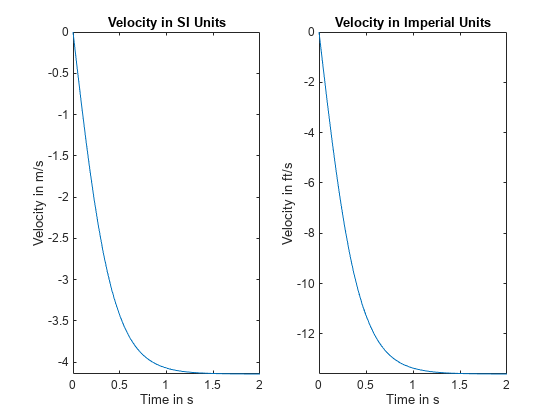

subplot(1,2,1)
fplot(data_SI,[0 2])
title('Velocity in SI Units')
xlabel('Time in s')
ylabel(['Velocity in ' symunit2str(units_SI)])
subplot(1,2,2)
fplot(data_Imperial,[0 2])
title('Velocity in Imperial Units')
xlabel('Time in s')
ylabel(['Velocity in ' symunit2str(units_Imperial)])

*Copyright 2012-2019 The MathWorks, Inc.*